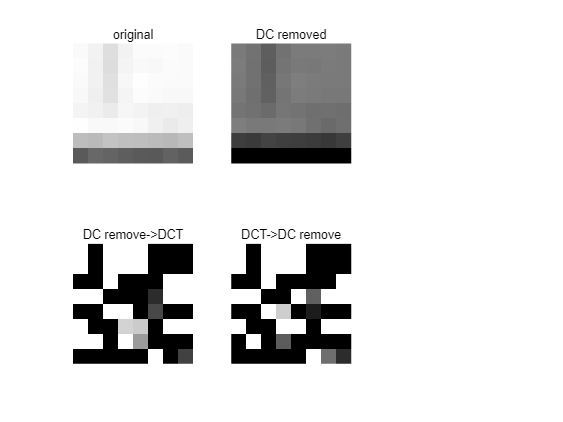

load JpegCoeff.mat;
load hall.mat;

[X,Y]=size(hall_gray);
L=min(X,Y);


L=8;
raw=hall_gray(64:71, 56:63);

dc_rem=raw-128;
dct_rem=DCT(dc_rem);
rem_dct=DCT(raw)-128.*DCT(ones(L));
err=1/(L*L).*norm(dct_rem-rem_dct);
 
figure
title("hello");
subplot(2,3,1);
imshow(raw);
title("original");
subplot(2,3,2);
imshow(raw-128);
title("DC removed");
subplot(2,3,4);
imshow(dct_rem);
title("DC remove->DCT");
subplot(2,3,5);
imshow(rem_dct);
title("DCT->DC remove"); 


fprintf("Average Forbenius Norm Error=%s\n",err);

Average Forbenius Norm Error=1.498209e+00
